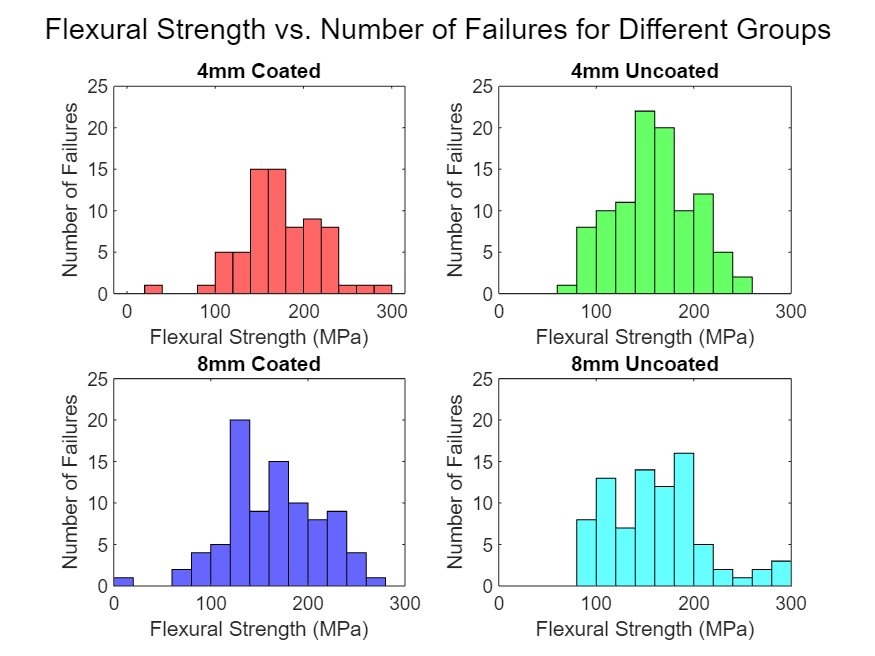

% This algorithm plots Flexural Strength vs Number of Failures,
% using data obtained during a 3-Point Bending Test on 
% glass rods of varying diameters
% ATTRIBUTION: algorithm was written by myself, with the help of
% ChatGPT to determine how to filter and sort data values for plotting
% Mathworks.com for MATLAB syntax

file = '/Users/vinay/Downloads/Lab-9_All_Sections.csv';
data = readtable(file,'HeaderLines',3);

p = pi;
number = data{1:403, 2};
label = data{1:403,3};
diameter = data{1:403,4};
radius = diameter./2;
support_span = data{1:403,5};
max_force = data{1:403,6};
flex_strength = (max_force.*support_span)./(p.*((radius).^3));

% Add flex_strength to the data table
data.flex_strength(1:403) = flex_strength;

% Filter out any erroneous data, as earlier plotting indicated that there
% was lots of data with stress values that are much too high
data = data(data.flex_strength <= 300, :);

% Group diameters between 3 and 5
fourmm_indices = diameter >= 3 & diameter <= 5;
fourmm_data = data(fourmm_indices, :);

% Group diameters between 7 and 9
eightmm_indices = diameter >= 7 & diameter <= 9;
eightmm_data = data(eightmm_indices, :);

% Split the 4mm group into 'coated' and 'uncoated'
fourmm_coated_indices = contains(fourmm_data{:,3}, 'coated')  & ~contains(fourmm_data{:,3}, 'uncoated');
fourmm_coated_data = fourmm_data(fourmm_coated_indices, :);

fourmm_uncoated_indices = contains(fourmm_data{:,3}, 'uncoated');
fourmm_uncoated_data = fourmm_data(fourmm_uncoated_indices, :);

% Split the 8mm group into 'coated' and 'uncoated'
eightmm_coated_indices = contains(eightmm_data{:,3}, 'coated') & ~contains(eightmm_data{:,3}, 'uncoated');
eightmm_coated_data = eightmm_data(eightmm_coated_indices, :);

eightmm_uncoated_indices = contains(eightmm_data{:,3}, 'uncoated');
eightmm_uncoated_data = eightmm_data(eightmm_uncoated_indices, :);

% Determine the overall range of flexural strengths
min_strength = min(data.flex_strength);
max_strength = max(data.flex_strength);

% Define the bin edges for intervals of 20 MPa
bin_edges = (floor(min_strength/20)*20):20:(ceil(max_strength/20)*20);
bin_centers = bin_edges(1:end-1) + 10; % The center of each bin for the scatter plot

% Function to count specimens in each bin
count_in_bins = @(group_data) histcounts(group_data, bin_edges);

% Count the number of specimens in each bin for all groups
fourmm_coated_counts = count_in_bins(fourmm_coated_data.flex_strength);
fourmm_uncoated_counts = count_in_bins(fourmm_uncoated_data.flex_strength);
eightmm_coated_counts = count_in_bins(eightmm_coated_data.flex_strength);
eightmm_uncoated_counts = count_in_bins(eightmm_uncoated_data.flex_strength);

% Define the bin edges for intervals of 20 MPa (assuming min_strength and max_strength are defined)
bin_edges = (floor(min_strength/20)*20):20:(ceil(max_strength/20)*20);

% Create the figure
figure;

% Histogram for 4mm Coated
subplot(2,2,1); % Creates a subplot in a 2x2 grid, at position 1
histogram(fourmm_coated_data.flex_strength, bin_edges, 'FaceColor', 'r');
title('4mm Coated');
xlabel('Flexural Strength (MPa)');
ylabel('Number of Failures');
ylim([0, 25]);

% Histogram for 4mm Uncoated
subplot(2,2,2); % Creates a subplot in a 2x2 grid, at position 2
histogram(fourmm_uncoated_data.flex_strength, bin_edges, 'FaceColor', 'g');
title('4mm Uncoated');
xlabel('Flexural Strength (MPa)');
ylabel('Number of Failures');
xlim([min(bin_edges), max(bin_edges)]);
ylim([0, 25]);

% Histogram for 8mm Coated
subplot(2,2,3); % Creates a subplot in a 2x2 grid, at position 3
histogram(eightmm_coated_data.flex_strength, bin_edges, 'FaceColor', 'b');
title('8mm Coated');
xlabel('Flexural Strength (MPa)');
ylabel('Number of Failures');
xlim([min(bin_edges), max(bin_edges)]);
ylim([0, 25]);

% Histogram for 8mm Uncoated
subplot(2,2,4); % Creates a subplot in a 2x2 grid, at position 4
histogram(eightmm_uncoated_data.flex_strength, bin_edges, 'FaceColor', 'c');
title('8mm Uncoated');
xlabel('Flexural Strength (MPa)');
ylabel('Number of Failures');
xlim([min(bin_edges), max(bin_edges)]);
ylim([0, 25]);

% Add a super title
sgtitle('Flexural Strength vs. Number of Failures for Different Groups'); % Super title for the figure


% Calculate and display mean and standard deviation for 4mm coated
mean_fourmm_coated = mean(fourmm_coated_data.flex_strength);
std_fourmm_coated = std(fourmm_coated_data.flex_strength);
fprintf('4mm Coated - Mean Flexural Strength: %.2f MPa, Standard Deviation: %.2f MPa\n', mean_fourmm_coated, std_fourmm_coated);

4mm Coated - Mean Flexural Strength: 174.46 MPa, Standard Deviation: 43.40 MPa



% Calculate and display mean and standard deviation for 4mm uncoated
mean_fourmm_uncoated = mean(fourmm_uncoated_data.flex_strength);
std_fourmm_uncoated = std(fourmm_uncoated_data.flex_strength);
fprintf('4mm Uncoated - Mean Flexural Strength: %.2f MPa, Standard Deviation: %.2f MPa\n', mean_fourmm_uncoated, std_fourmm_uncoated);

4mm Uncoated - Mean Flexural Strength: 159.51 MPa, Standard Deviation: 40.95 MPa



% Calculate and display mean and standard deviation for 8mm coated
mean_eightmm_coated = mean(eightmm_coated_data.flex_strength);
std_eightmm_coated = std(eightmm_coated_data.flex_strength);
fprintf('8mm Coated - Mean Flexural Strength: %.2f MPa, Standard Deviation: %.2f MPa\n', mean_eightmm_coated, std_eightmm_coated);

8mm Coated - Mean Flexural Strength: 164.89 MPa, Standard Deviation: 47.98 MPa



% Calculate and display mean and standard deviation for 8mm uncoated
mean_eightmm_uncoated = mean(eightmm_uncoated_data.flex_strength);
std_eightmm_uncoated = std(eightmm_uncoated_data.flex_strength);
fprintf('8mm Uncoated - Mean Flexural Strength: %.2f MPa, Standard Deviation: %.2f MPa\n', mean_eightmm_uncoated, std_eightmm_uncoated);

8mm Uncoated - Mean Flexural Strength: 160.97 MPa, Standard Deviation: 49.13 MPa
